M = 1.5;
m = 0.25;
L = 0.013686;
R = 0.015;
Iw = 1.5498371e-5;
Ip = 0.005;
g = 9.81;

C1 = M+2*m+2*Iw/R^2;
C2 = M*L;
C3 = M*L^2+Ip;
C4 = M*L*g;

S1 = -C2*C4/(C1*C3-C2^2);
S2 = C1*C4/(C1*C3-C2^2);
b1 = (C3+C2*R)/(C1*C3*R-C2^2*R);
b2 = -(C2+C1*R)/(C1*C3*R-C2^2*R);

phi = 0.01;
a_dodot = (M*g*L*sin(phi))/(M*L*cos(phi)+R*(M+2*m+2*Iw/R^2))

a_dodot = 0.0383

A = [0 1 0 0;
     0 0 S1 0;
     0 0 0 1;
     0 0 S2 0]

A =          0    1.0000         0         0
         0         0   -0.3804         0
         0         0         0    1.0000
         0         0   39.6138         0



B = [0;b1;0;b2]

B =          0
   34.2835
         0
 -322.6318



C= [1 0 0 0;
    0 0 1 0];

Q = [1 0 0 0;
     0 1 0 0;
     0 0 1 0;
     0 0 0 1];
R1 = 10000 ;
v = 1;
% Giai ARE: A'P + PA + Q - nu*PBR^-1B'P =0
[X,~,~] = care(A, sqrt(v)*B, 15*Q, R1);

% Bo dieu khien theo de bai: K = -R^{-1}B'P
K1 = -inv(R1)*(B'*X)

K1 =     0.0387    0.0792    0.3590    0.0694


C2 = [1 0 0 0];

D2 = [-3.829 0 0 0];

Gamma = [0 1 0 0;
     0 0 1 0;
     0 0 0 0;
     0 0 0 1];
n = size(A, 1);
m = size(Gamma, 1);
q = size(B, 2);

% Lập ma trận khối M và vector v theo phương pháp Kronecker
M = [kron(Gamma.', eye(n)) - kron(eye(m), A), -kron(eye(m), B);
     kron(eye(m), C2), zeros(numel(D2), q*m)];
v = [zeros(n*m, 1); -D2(:)];

% Giải hệ phương trình x = [P(:); Y(:)]
x = M \ v;

% Trích xuất và định dạng lại ma trận P
P = reshape(x(1:n*m), n, m);
Y = reshape(x(n*m+1:end), q, m);

K2 = Y - K1*P

K2 =    -0.1483   -0.3034   -0.2363         0



sai_so = norm(M*x - v);
disp(['Sai số của hệ phương trình Sylvester: ', num2str(sai_so)]);

Sai số của hệ phương trình Sylvester: 2.9788e-16


if sai_so > 1e-6
    warning('Hệ phương trình không có nghiệm chính xác, kiểm tra lại điều kiện Transmission Zeros!');
end
simOut = sim('graph_canbang')

simOut =   Simulink.SimulationOutput:

                   tout: [148x1 double] 
                      u: [1x1 struct] 
                      y: [1x1 struct] 
                      z: [1x1 struct] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


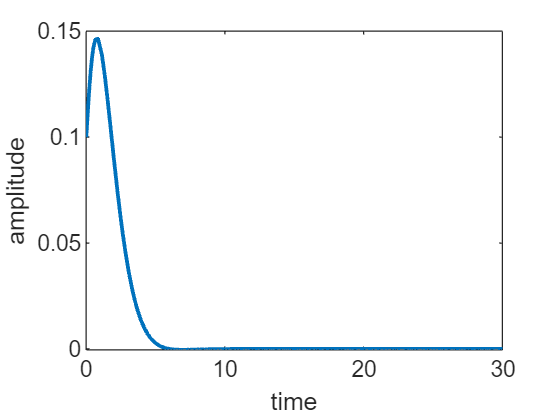

z = simOut.z.signals.values;
tz = simOut.z.time;
figure;
plot(tz, z, 'linewidth', 1.5);
xlabel('time');
ylabel('amplitude');

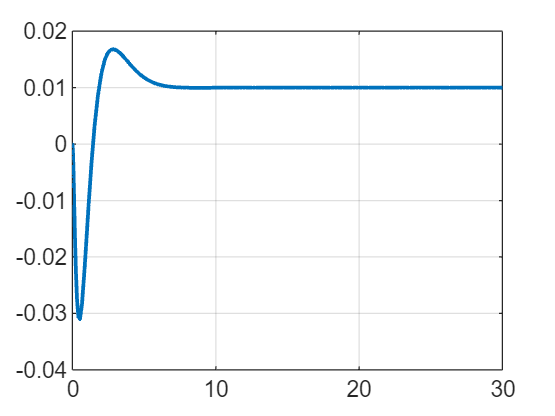


y = simOut.y.signals.values;
ty = simOut.y.time;
plot(ty, y(:,2), 'linewidth', 1.5);
grid on

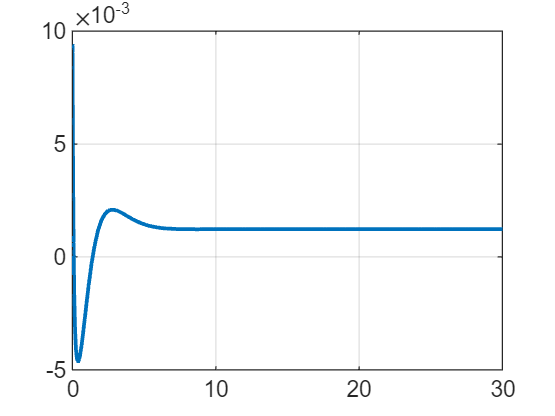


u = simOut.u.signals.values;
tu = simOut.u.time;
figure;
plot(tu, u, 'Linewidth', 1.5)
grid on;